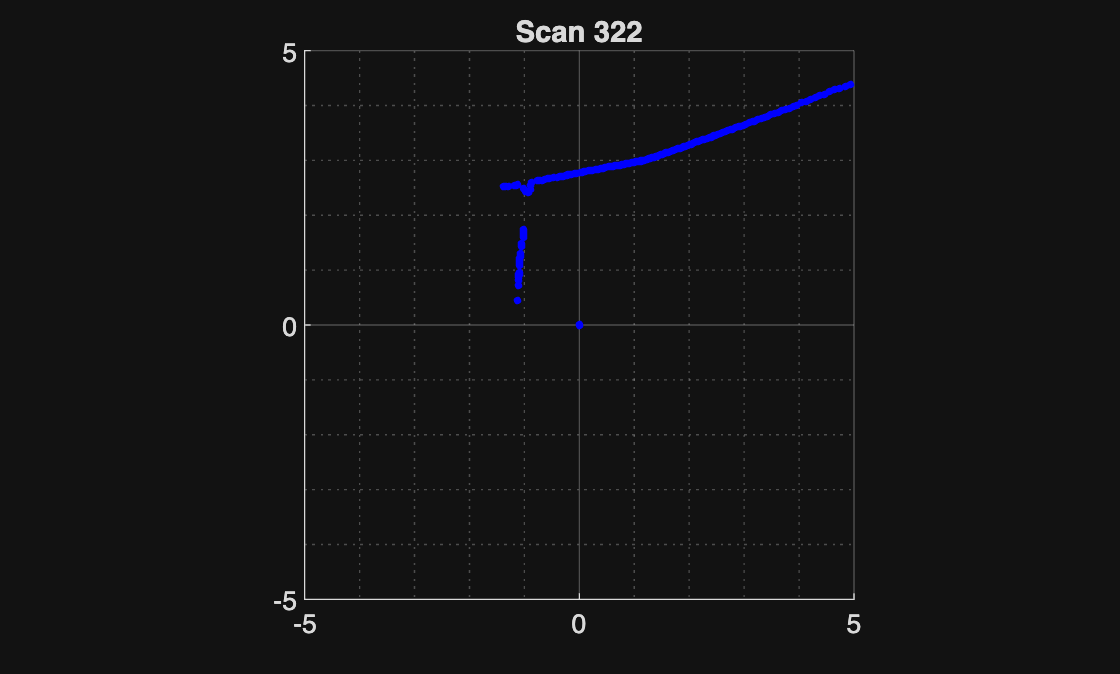

clc; clear; close all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% change suffix from 1 to 5 to get different data files

filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_test_street_5.csv';
filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_xy_test_street_5.csv';
filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_velocities_x_y_test_street_5.csv';
filepath_rssi = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_rssi_test_street_5.csv';

% ===== for triming long measurements uncomment the function below ===== %

% trimLidarData(filepath_xy_scan , filepath_r_scan, filepath_vx_vy, filepath_rssi, 1000, 1600)

% ===== load data ===== %

xy_data = readmatrix(filepath_xy_scan);
r_data = readmatrix(filepath_r_scan);
v_data = readmatrix(filepath_vx_vy);
rssi_data = readmatrix(filepath_rssi);

t_r_ = r_data(:,1);
r_all_ = r_data(:,3);

t_xy_ = xy_data(:,1); 
x_all_ = xy_data(:, 2);
y_all_ = xy_data(:, 3);

t_velocity = v_data(:,1);
vx_all= v_data(:,2); 
vy_all = v_data(:,3);  
v = v_data(:,4);

t_rssi = rssi_data(:,1); 
rssi = rssi_data(:,2);

% ===== synchronize ===== %

scanPointNumbers = 421;  % point numbers are reduced to 421 instead of 811 (only the right area will be processed)

% ===== keep only the values with proper velocity ( vel < 20 m/s and vel > 0 m/s) ===== % 

[x_filtered, y_filtered, vx_filtered, vy_filtered, v_filtered, rssi_filterd, r_filtered]= filterAllValuesWithProperVelocities(x_all_, y_all_, vx_all, vy_all, v, rssi, r_all_, scanPointNumbers);

% ===== segmentation and clustering ===== %

[x_points_in_critical_area, y_points_in_critical_area] = ExtractPointsInCriticalArea(x_filtered, y_filtered); 
segments = clusterSegments(x_points_in_critical_area, y_points_in_critical_area);
clusters = mergeSegmentsToClustersPerScan(segments);
clusters_with_id = trackClustersBetweenScans(clusters);
objects = classifyClusters(clusters_with_id);  % objects: id, mean of all lengths for this id, category
plotObjects(x_filtered, y_filtered, clusters_with_id, objects);


% ================== velocity based detection ================== %%

% ===== calculate mean/median values for each scan ===== % (column 1: right side, colum 2: left side, column 3: whole scan)

%[v_mean, v_median, point_index_median_velocities] = computeMeanMedianVelocity(v_filtered, r_filtered, scanPointNumbers);

% ===== filtering the median and mean values for ego motion estimation ===== %

%[alphafiltered_median, alphafiltered_mean] = alphaFilter(v_median(:,1), v_mean(:,1)); % alpha filter to estimate the ego velocity

% ===== compute and plot peak velocities ===== %

% v_median_right_area = v_median(:,1);
% peakVelocities = detectPointWithPeakVelocity(v_median_right_area, point_index_median_velocities, rssi_filterd, r_filtered, alphafiltered_median);
% plotPointsWithDangerousVelocity(x_filtered, y_filtered, peakVelocities);

% ===== theta (the angle between the vector of velocities: (vx,vy)) ===== %

% plotTheta(x_all_, y_all_, vx_all, vy_all);
% plotTheta(x_filtered, y_filtered, vx_filtered, vy_filtered);

% ================== the end ================== %


